**Computer Exercise 3.2.15**

This program will solve the equation$\frac{1}{2}x^2 + x + 1 = e^x$ by finding the root of $f(x) = \frac{1}{2}x^2 + x + 1 - e^x$ closest to an initial point $x_0 = 1$.

The program will terminate when either the number of iterates exceeds a set amount or when the following error condition is met: $| x_{n} - x_{n-1} | < \frac{1}{2} \times 10^{-5}$ 

Iterate number, corresponding x value, and the the function at x will be displayed.

syms x; %program is modified to only take a function
        %as input by having the derivative evaluated
        %within the Newton algorithm; to accomplish this
        %symbolic functions are utilized

%%inputs for Newton's method        

f = (1/2)*(x^2) + x + 1 - exp(x); %symbolic function

x0=1; %initial point

N=6; %max number of iterates

err = 0.5 * 10^(-5); %error tolerance for successive points

m=1; %if root multiplicity is known ahead of time,
     %this value can be changed to account for
     %root multiplicity and use the modified
     %Newton's method

root1 = newton(f, x0, N, err, m);

n = 0, xn =   1.000000000000, f(xn) = -2.182818284590e-01, error = 1.000000000000e+00 
n = 1, xn =   0.696105595589, f(xn) = -6.753849522062e-02, error = 3.038944044113e-01 
n = 2, xn =   0.478112902284, f(xn) = -2.061871165303e-02, error = 2.179926933045e-01 
n = 3, xn =   0.325285123719, f(xn) = -6.234992633393e-03, error = 1.528277785653e-01 
n = 4, xn =   0.219857803679, f(xn) = -1.873025059444e-03, error = 1.054273200397e-01 
n = 5, xn =   0.147933877018, f(xn) = -5.601354445951e-04, error = 7.192392666102e-02 
n = 6, xn =   0.099236404329, f(xn) = -1.670001644371e-04, error = 4.869747268924e-02 


After six iterates, there is no sign of the beloved quadratic convergence of Newton's method; the program is painfully slow past six iterates so I stopped it there. There is a reason for this slow convergence which we can investigate with the following plot:

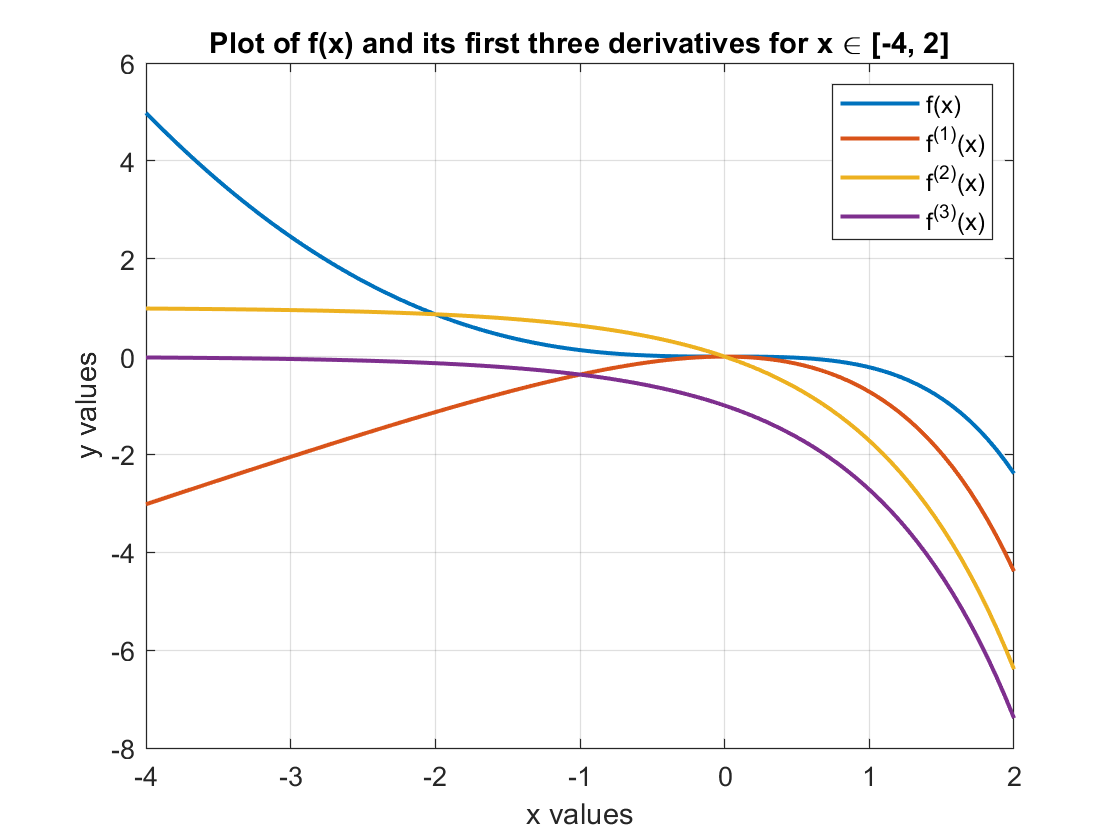

a=4;
fd = diff(f);
fd2 = diff(fd);
fd3 = diff(fd2);

clf
xvals = linspace(-a,a-2);

yvals1 = vpa(subs(f, x, xvals), 16);
yvals2 = vpa(subs(fd, x, xvals), 16);
yvals3 = vpa(subs(fd2, x, xvals), 16);
yvals4 = vpa(subs(fd3, x, xvals), 16);

h = plot(xvals, yvals1, xvals, yvals2, xvals, yvals3, xvals, yvals4);
thickness = 1.5;
set(h(1),'linewidth', thickness);
set(h(2),'linewidth', thickness);
set(h(3),'linewidth', thickness);
set(h(4),'linewidth', thickness);
legend('f(x)', 'f^{(1)}(x)', 'f^{(2)}(x)', 'f^{(3)}(x)')
title('Plot of f(x) and its first three derivatives for x \in [-4, 2]')
grid on
xlabel('x values')
ylabel('y values')

It appears that there is a root at (x,y) = (0,0), but $f(x)$shares this exact same root with both $f'(x)$and $f''(x)$! Therefore, the root has multiplicity of three! We can recover the quadratic convergence by using $m=3$ as an input in the Newton algorithm:

root_mod = newton(f, x0, 10, err, 3); %repeat the algorithm with N=10 and m=3

n = 0, xn =   1.000000000000, f(xn) = -2.182818284590e-01, error = 1.000000000000e+00 
n = 1, xn =   0.088316786766, f(xn) = -1.173900339448e-04, error = 9.116832132340e-01 
n = 2, xn =   0.000653786133, f(xn) = -4.658293544846e-11, error = 8.766300063257e-02 
n = 3, xn =   0.000000035621, f(xn) = -7.533139829068e-24, error = 6.537505121852e-04 
n = 4, xn =   0.000000000000, f(xn) = -1.970423440204e-49, error = 3.562124467583e-08 


Amazing! We have a quadratic convergence again after only four iterates with an insane amount of accuracy for the function near the root (on the order of $10^{-49}$).

function root = newton(f, x0, N, err, m)
    n=0; %initialize iterate 
    syms x; %symbols needs to be redeclared otherwise
            %algorithm yields an error
   
    fd = diff(f); %symbolically evaluate derivative of
                  %input function
    
    y = subs(f, x, x0); %evaluate input function at x0
    
    dy = subs(fd, x, x0); %evaluate derivative at x0
    
    xn = x0; %initialize iterate x value for loop
    
    error = 1; %initialize error to any value such that error < err
    
    fprintf(['n = %d, xn = %16.12f, f(xn) = %16.12e, ' ...
        'error = %16.12e \n'], n, xn, y, error)
    %display the zeroth iterate
    while (error > err) && (n < N)            
        root = xn - ((m*y)/dy); %evaluate subsequent point 
                                %using Newton's method formula
        y = subs(f, x, root);        
        dy = subs(fd, x, root);        
        error = abs(xn -root); %error value between successive points        
        xn = root;        
        n = n + 1; %increment iteration number     
        fprintf(['n = %d, xn = %16.12f, f(xn) = %16.12e, ' ...
            'error = %16.12e \n'], n, xn, y, error)
        %display nth iterate
    end
end